d = readtable('data.csv');

data = readtable('data.csv');
D = table2array(data(1:end, :));
isnumeric(D)

ans = logical
   1


PERFORMING PCA on encoded data 

coeff: coefficients per component loadings?

score: rows are observations and cols components 

latent: col vector of eigenvalues 

tsquared:  col vectro sum of standarized scores/obsversation 

mu: if centered true: means of vars in X 

[raw.coeff, raw.score, raw.latent, raw.tsquared, raw.explained, raw.mu] = pca(D);

[raw.coeff, raw.score, raw.latent, raw.tsquared, raw.explained, raw.mu]= pca(D);

VISUALIZING

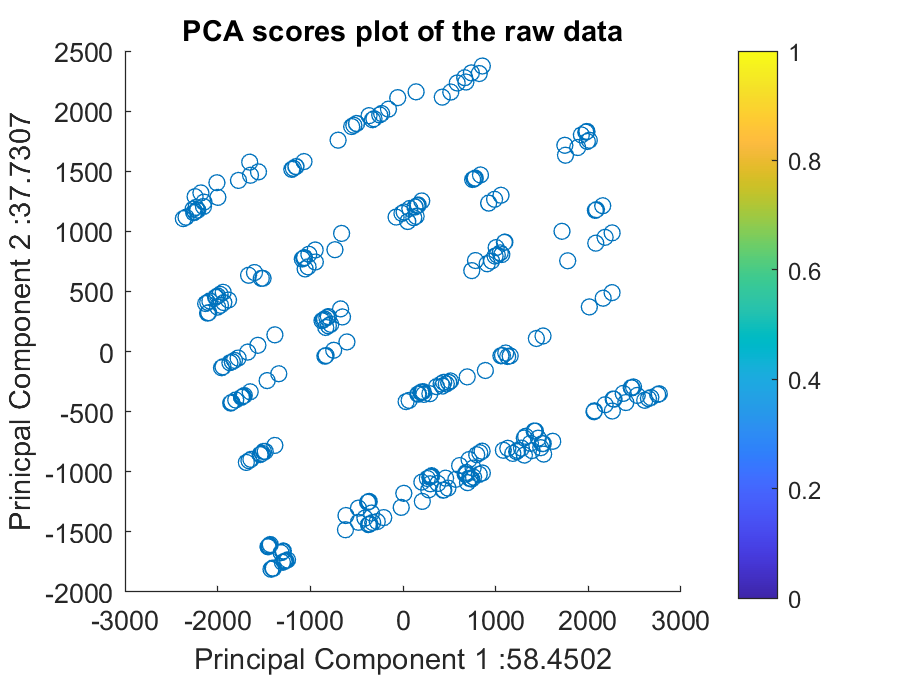

% first two components
scatter(raw.score(:,1),raw.score(:,2))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(raw.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(raw.explained(2))))
title('PCA scores plot of the raw data')
hold off

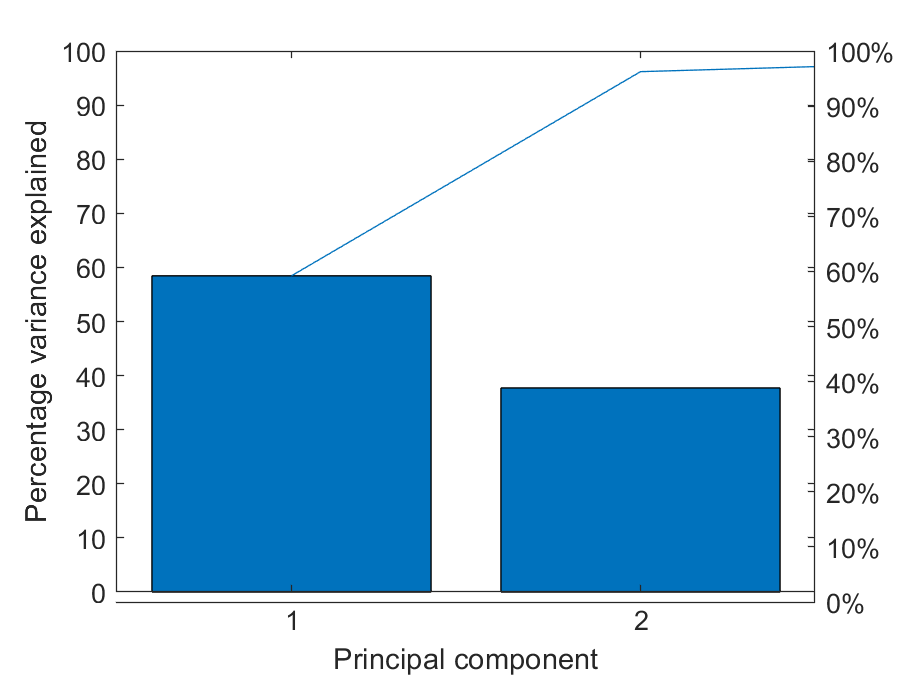


figure 
pareto(raw.explained)
xlabel('Principal component')
ylabel('Percentage variance explained')

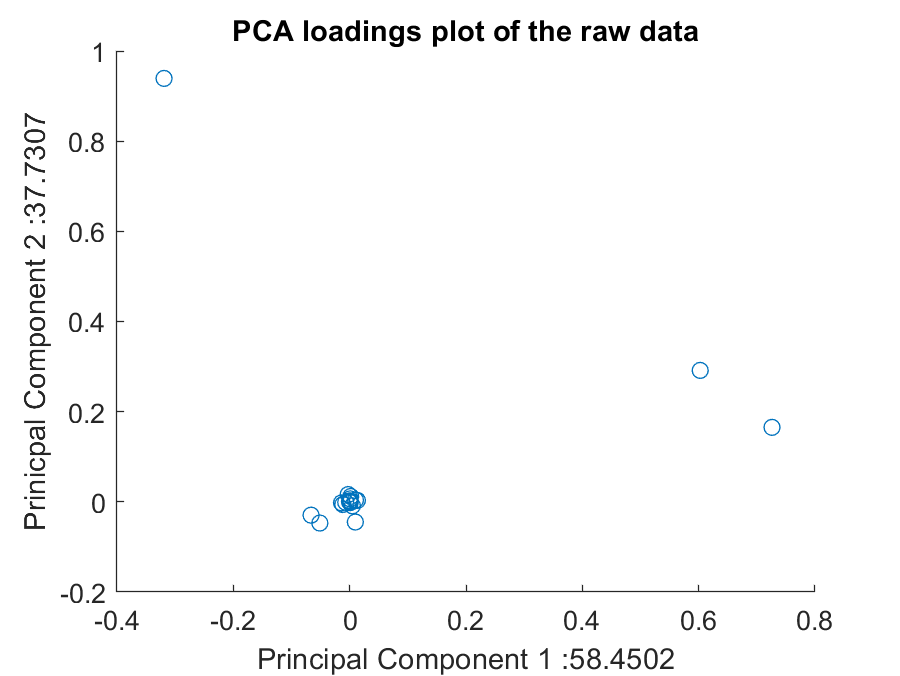


figure 
scatter(raw.coeff(:,1),raw.coeff(:,2))
xlabel(strcat('Principal Component 1 : ', num2str(raw.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(raw.explained(2))))
title('PCA loadings plot of the raw data')

% STANDARIZE OR NORMALIZE???
% x = mean(D);
% norm = D - x;
maxes = max(D);
[r,c]= size(D);
norm = zeros(r, c);
for i=1:size(D,2)
 norm(:,i) = D(:,i)/maxes(i);
end
norm = table2array(table(norm));

[normed.coeff, normed.score, normed.latent, normed.tsquared, normed.explained, normed.mu]= pca(norm);

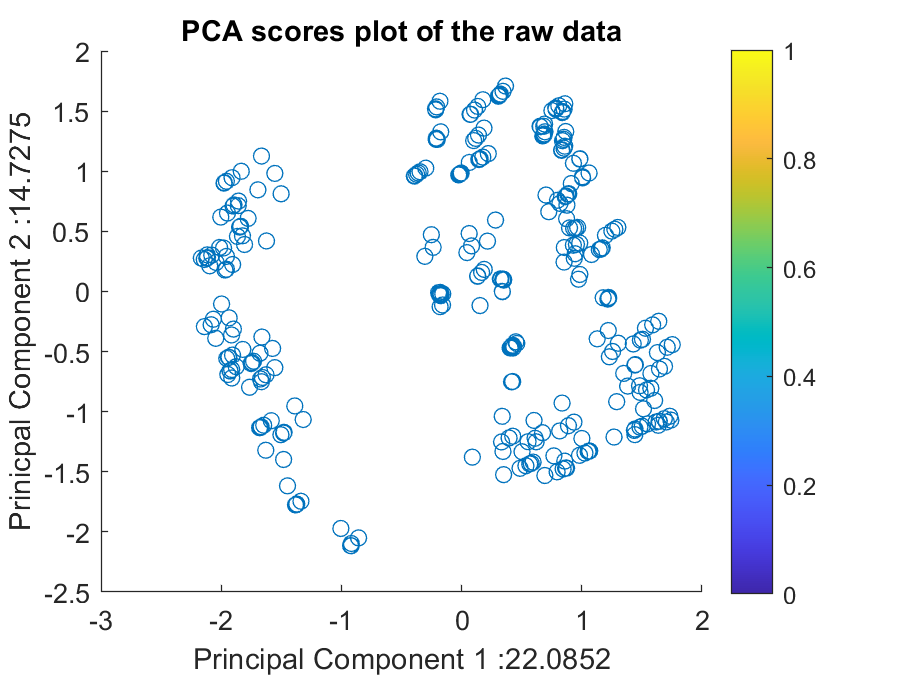

scatter(normed.score(:,1), normed.score(:,2))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(normed.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(normed.explained(2))))
title('PCA scores plot of the raw data')
hold off

figure
pareto(normed.explained)

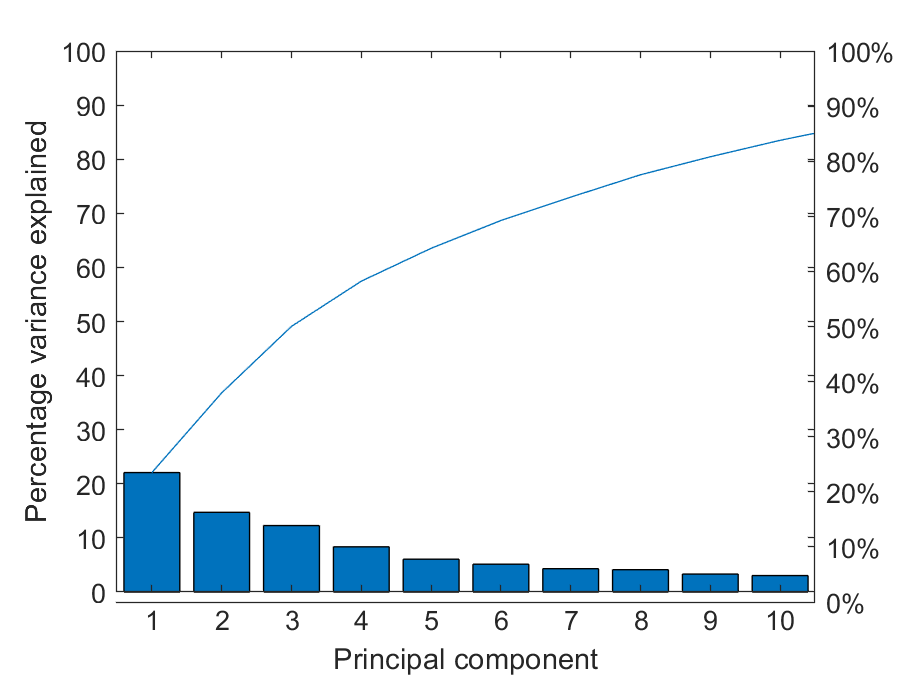

xlabel('Principal component')
ylabel('Percentage variance explained')

scale = zscore(norm);
[scaled.coeff, scaled.score, scaled.latent, scaled.tsquared, scaled.explained, scaled.mu]= pca(scale);

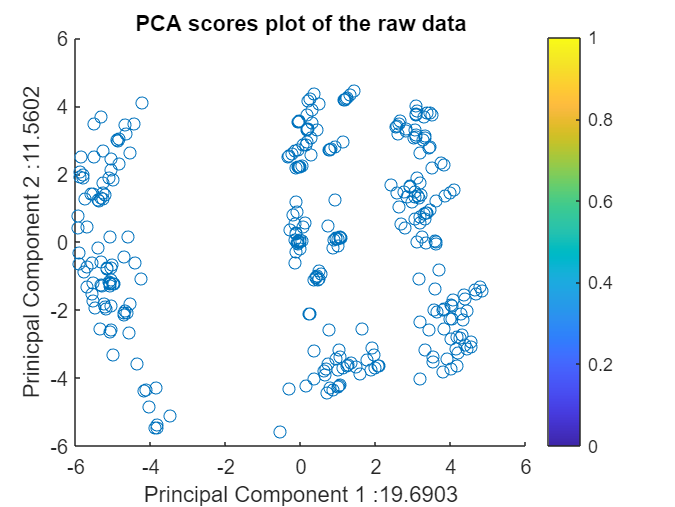

scatter(scaled.score(:,1),scaled.score(:,2))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(scaled.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(scaled.explained(2))))
title('PCA scores plot of the raw data')
hold off

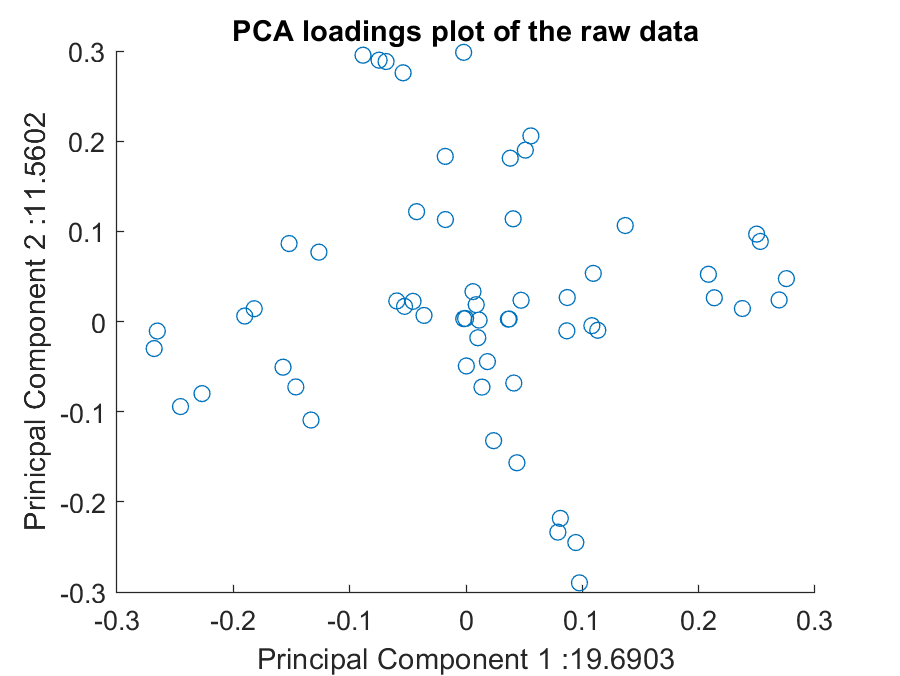


figure
scatter(scaled.coeff(:,1),scaled.coeff(:,2))
xlabel(strcat('Principal Component 1 : ', num2str(scaled.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(scaled.explained(2))))
title('PCA loadings plot of the raw data')

FOUR FEATURES TO LOOK INTO 

E

STRAIN_BREAK

STRENGTH

IMPACT

seperate all of them into different datasets and perform pca to them

TO PREDICT

32: E B 

33: B strength

34: B strainbreak 

35 : B impact 

36: B OP E matrix

37 : B OPStrengt

38: B OP strainbreak 

39 : B OP impact 

ORIGINAL 

18 : M E

19 : M Strength

20 : M SB

21: M impact 

22: I E

23 : I Strength

24 : I sttrain break

25 : I impact 

crystallinity and viscosity part of given inputs 

standard = norm(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 26 27 28 29 30 31 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 ])

standard =          0         0         0    1.0000    1.0000    0.2857         0    1.0000    1.0000         0         0    0.7143    1.0000    0.5000    0.5000         0         0    0.4860    0.9677    0.0109    0.0017         0         0         0    1.0000         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000    1.0000    0.2857         0    1.0000    1.0000         0         0    0.7143    0.4000    0.8000    0.2000         0         0    0.4860    0.9677    0.0109    0.0017         0         0         0    1.0000         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000    1.0000    0.2857         0    1.0000    1.0000         0         0    0.7143    0.2

E = table(standard(:,:), norm(:,18),norm(:,22) , norm(:,32),norm(:, 36));
E = table2array(E);

% STRENGTH 
S = table2array(table(standard(:,:), norm(:,19),norm(:,23) , norm(:,33),norm(:, 37)));

% STRAIN BREAK 
SB = table2array(table(standard(:,:), norm(:,20),norm(:,24) , norm(:,34),norm(:, 38)));

% IMAPCT
I = table2array(table(standard(:,:), norm(:,21),norm(:,22) , norm(:,35),norm(:, 39)));

[elas.coeff, elas.score, elas.latent, elas.tsquared, elas.explained, elas.mu]= pca(E);

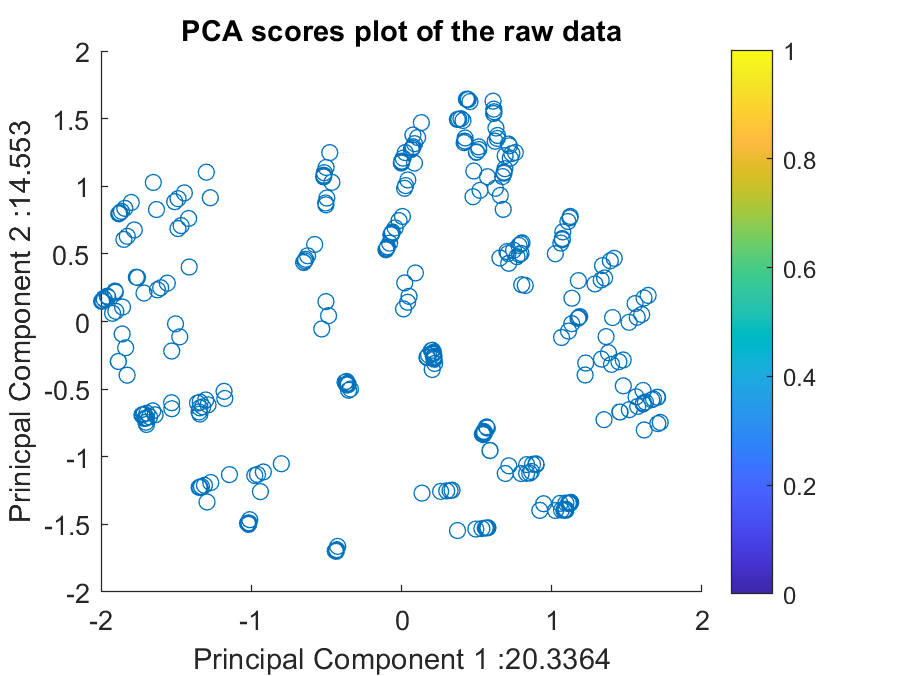

scatter(elas.score(:,1), elas.score(:,2))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(elas.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(elas.explained(2))))
title('PCA scores plot of the raw data')
hold off

figure
pareto(elas.explained)

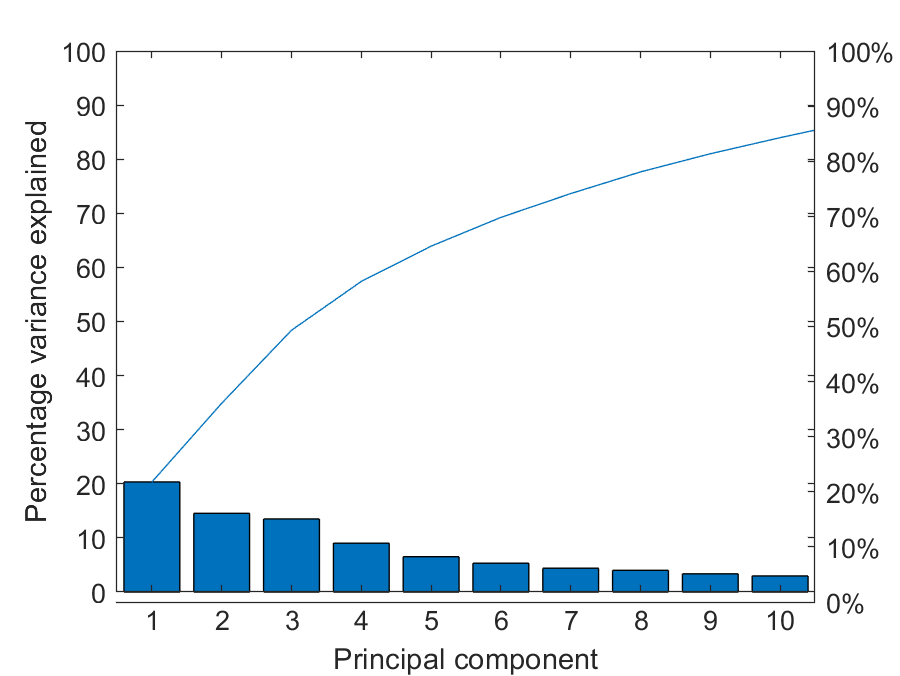

xlabel('Principal component')
ylabel('Percentage variance explained')

[elas.coeff, elas.score, elas.latent, elas.tsquared, elas.explained, elas.mu]= pca(E);

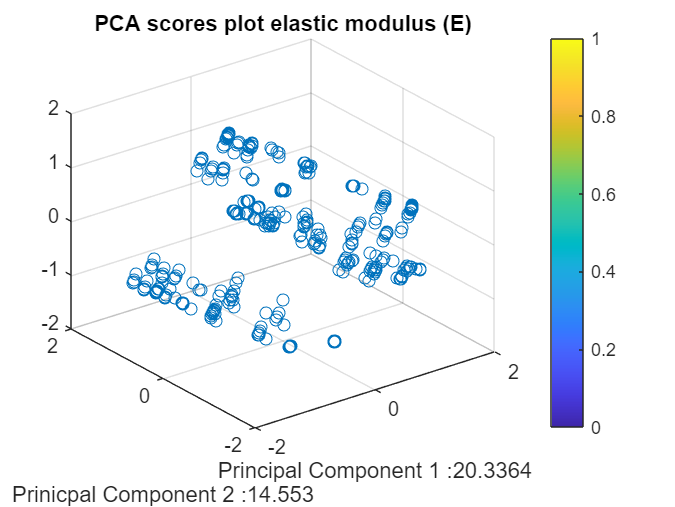

scatter3(elas.score(:,1), elas.score(:,2), elas.score(:,3))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(elas.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(elas.explained(2))))
title('PCA scores plot elastic modulus (E)')
hold off

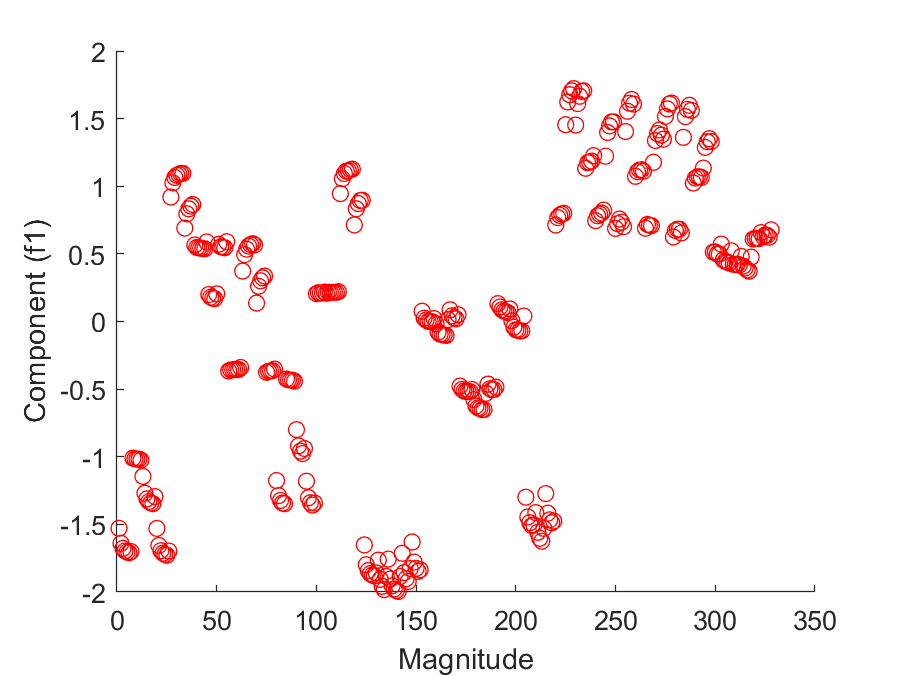

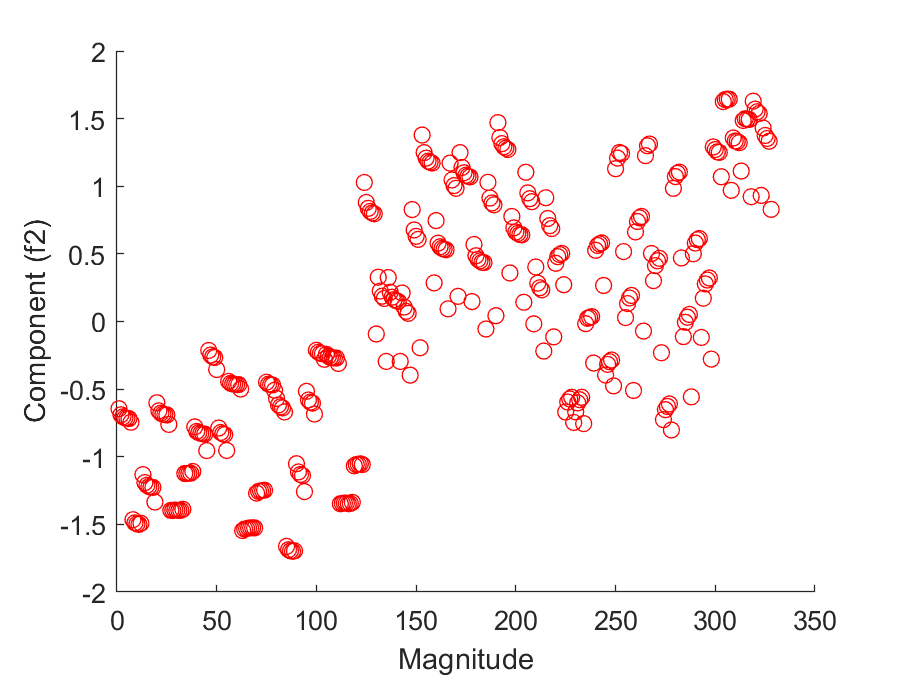

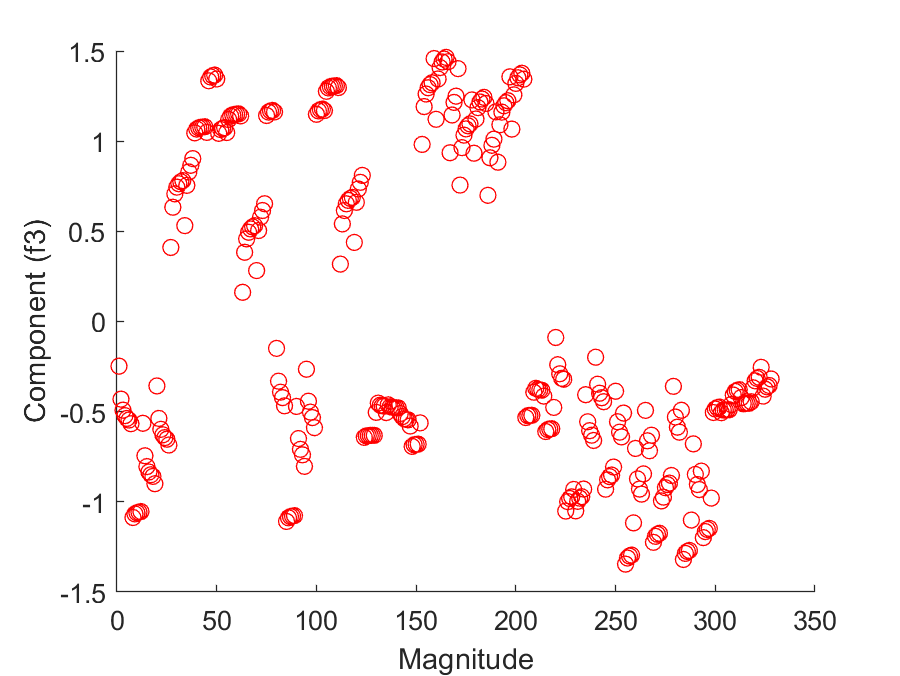

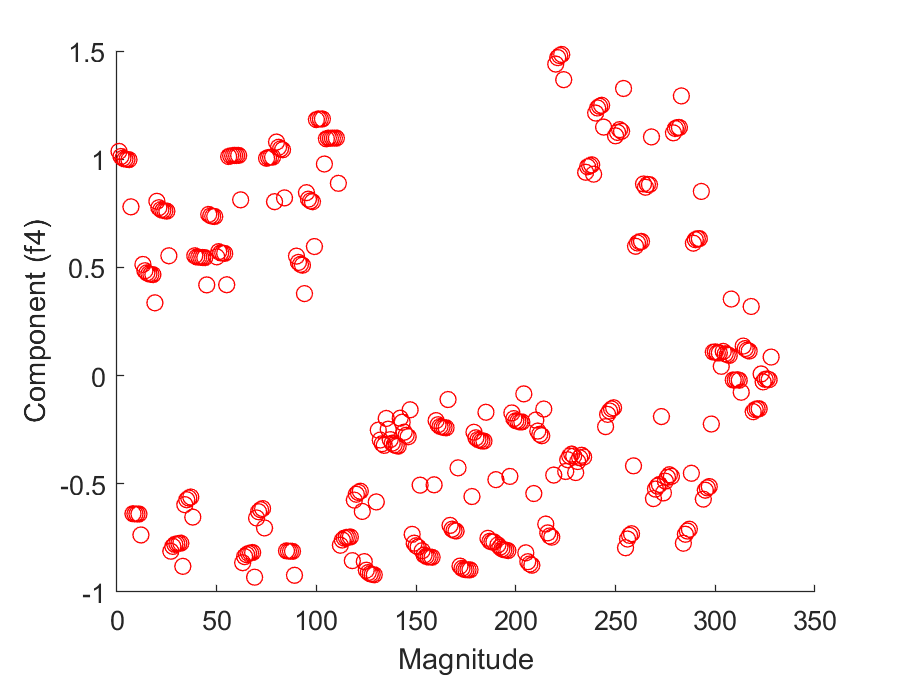

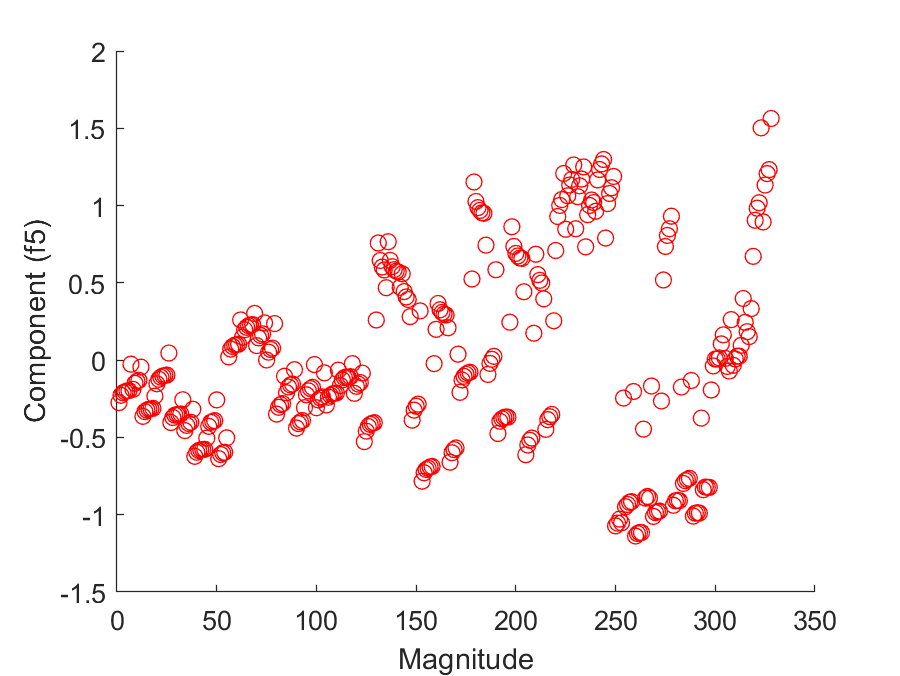



plotpca={'f1','f2','f3','f4','f5'};
for p=1:5
    figure('Name',plotpca{p},'NumberTitle','off');

    score_length = size(elas.score, 1);
    tx_vect= elas.score(1:score_length, p);
    scatter(1:score_length,tx_vect,'r')
    xlabel('Magnitude') 
    ylabel("Component ("+ plotpca{p}+")")
end


% TODO: PCA, 'Algorithm','als'

STRENGTH


[str.coeff, str.score, str.latent, str.tsquared, str.explained, str.mu]= pca(S, 'Algorithm','als');

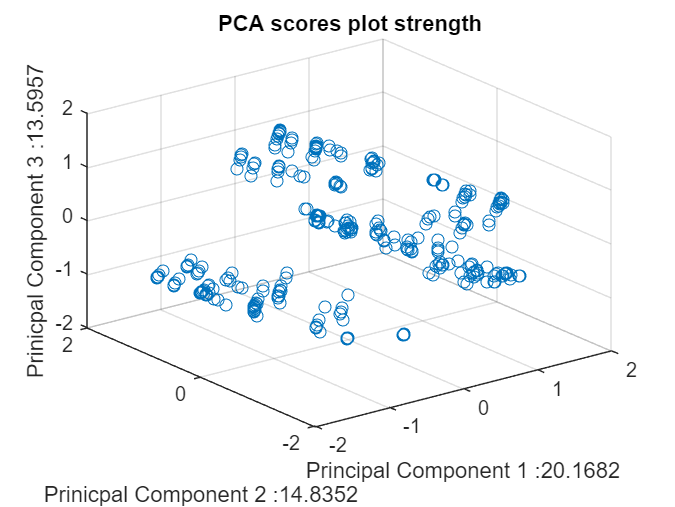

scatter3(str.score(:,1), str.score(:,2), str.score(:,3))
xlabel(strcat('Principal Component 1 : ', num2str(str.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(str.explained(2))))
zlabel(strcat('Prinicpal Component 3 : ', num2str(str.explained(3))))
title('PCA scores plot strength')

As of 21/04:

iwith the first 3 components, they gather most 20, 14, 13, 9... 

first would be the family or so, we can distinguish three groups in the diagonal axis. SEcond component is along the groups!! (this would be the crucial to regression given family? ) then 3rd gives more into groups? only doing 2 components seems like a crosssetion of the 3 groups, uppest middel and lower 

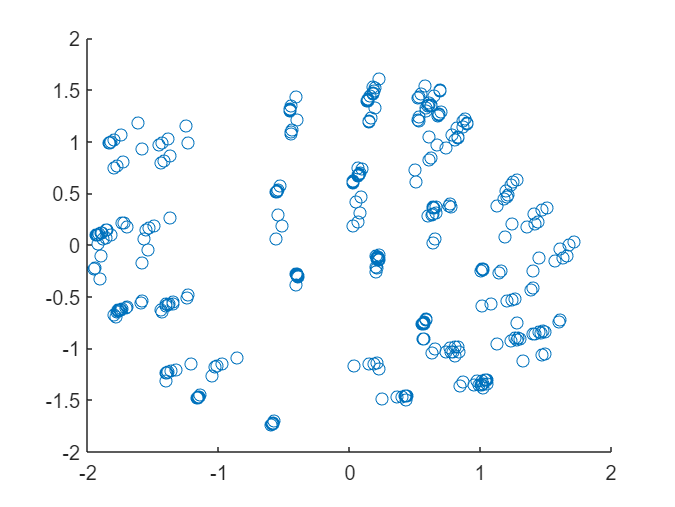

scatter(str.score(:,1), str.score(:,2))


% from graph; if PC3 >0 -> 1group 
% PC3<0 and PC1 >0 ->froup 2
count1 = 1;count2 =1; count3 = 1;
first_group = zeros (length(str.score),1);
second_group = zeros (length(str.score),1);
third_group = zeros (length(str.score),1);
for i=1:length(str.score)
    if str.score(i,3)> 0 
        first_group(count1) = i;
        count1 = count1+1;
    else
        if str.score(i,1)> 0
            second_group(count2) = i;
            count2 = count2+1;
        else 
            third_group(count3) =i;
            count3 = count3+1;
        end
    end
end


[sb.coeff, sb.score, sb.latent, sb.tsquared, sb.explained, sb.mu]= pca(SB);

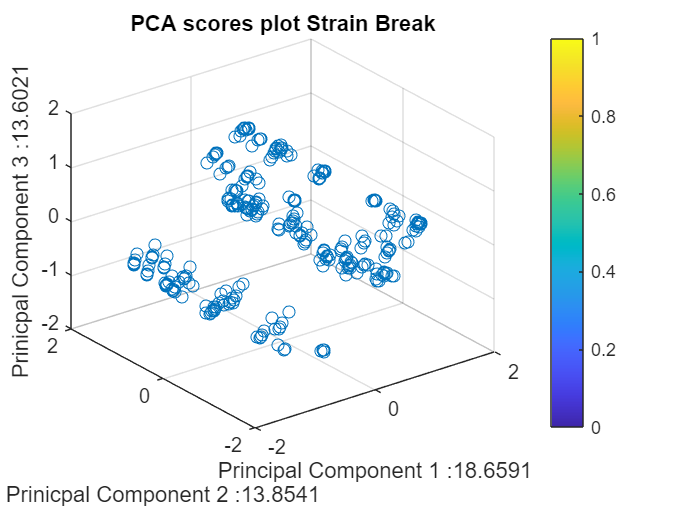

scatter3(sb.score(:,1), sb.score(:,2), sb.score(:,3))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(sb.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(sb.explained(2))))
zlabel(strcat('Prinicpal Component 3 : ', num2str(sb.explained(3))))
title('PCA scores plot Strain Break')
hold off

[imp.coeff, imp.score, imp.latent, imp.tsquared, imp.explained, imp.mu]= pca(I);

scatter3(imp.score(:,1), imp.score(:,2), imp.score(:,3))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(imp.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(imp.explained(2))))'

ans =   Text (Prinicpal Component 2 :14.4998) with properties:

                 String: 'Prinicpal Component 2 :14.4998'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-2.5975 -0.5919 -3.2922]
                  Units: 'data'

  Show all properties


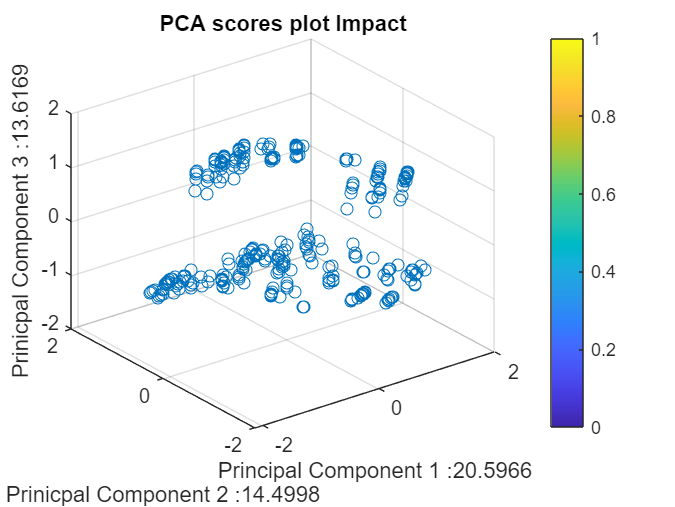

zlabel(strcat('Prinicpal Component 3 : ', num2str(imp.explained(3))))
title('PCA scores plot Impact')
hold off


% SELECTIN THE BEST 10 FEATURES?
[foo, feature_idx] = sort(imp.latent, 'descend');
selected_projected_data = imp.score(:, feature_idx(1:10));
selected_projected_data

selected_projected_data =    -1.5226   -0.6475    0.3134    1.0016   -0.3721   -0.4519   -0.1199    0.3089    0.3253   -0.0147
   -1.7361   -0.8154    0.1755    0.9783   -0.3396   -0.3750   -0.2674    0.1373    0.3370   -0.1556
   -1.7777   -0.8524    0.1345    0.9707   -0.3185   -0.3546   -0.3154    0.1042    0.3399   -0.2168
   -1.7943   -0.8683    0.1148    0.9670   -0.3066   -0.3451   -0.3392    0.0911    0.3412   -0.2494
   -1.7949   -0.8713    0.1062    0.9652   -0.2979   -0.3417   -0.3507    0.0908    0.3416   -0.2694
   -1.7960   -0.8736    0.1009    0.9641   -0.2930   -0.3396   -0.3577    0.0900    0.3419   -0.2810
   -1.7934   -0.9093    0.0903    0.7388   -0.0974   -0.1157   -0.6391    0.0910    0.2765   -0.3881
   -1.0817   -1.7531   -0.2123   -0.6574   -0.2977    0.0273   -0.3891    0.5609    0.9751    0.5144
   -1.1268   -1.7933   -0.1881   -0.6629   -0.2729    0.0777   -0.5263    0.4815    0.9626    0.3278
   -1.1408   -1.8060   -0.1799   -0.6647   -0.2642    0.0943   -0

FAMILY CLUSTERING

The groups are even more distinct;, it seems theycomponents are different order (P3 and P2)and has been sort of titled upwards.NOw it is the y axis thatwe will perform a regression in 

dF = readtable('data_families.csv');

dF = table2array(dF(1:end, :));
maxes = max(dF);
[r,c]= size(dF);
normed = zeros(r, c);
for i=1:c
 normed(:,i) = dF(:,i)/maxes(i);
end

standard = normed(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 26 27 28 29 30 31 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68])

standard =          0    0.5000         0    1.0000    1.0000    0.2857         0    1.0000    1.0000         0         0    0.7143    1.0000    0.5000    0.5000         0         0    0.4860    0.9677    0.0109    0.0017         0         0         0    1.0000         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0    1.0000
         0    0.5000         0    1.0000    1.0000    0.2857         0    1.0000    1.0000         0         0    0.7143    0.4000    0.8000    0.2000         0         0    0.4860    0.9677    0.0109    0.0017         0         0         0    1.0000         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0        

EF = table(standard(:,:), normed(:,18),normed(:,22) , normed(:,32),normed(:, 36));
EF = table2array(EF);

% STRENGTH 
SF = table2array(table(standard(:,:), normed(:,19),normed(:,23) , normed(:,33),normed(:, 37)));

% STRAIN BREAK 
SBF = table2array(table(standard(:,:), normed(:,20),normed(:,24) , normed(:,34),normed(:, 38)));

% IMAPCT
IF = table2array(table(standard(:,:), normed(:,21),normed(:,22) , normed(:,35),normed(:, 39)));

[impF.coeff, impF.score, impF.latent, impF.tsquared, impF.explained, impF.mu]= pca(IF);

scatter3(impF.score(:,1), impF.score(:,2), impF.score(:,3))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(impF.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(impF.explained(2))))'

ans =   Text (Prinicpal Component 2 :14.6126) with properties:

                 String: 'Prinicpal Component 2 :14.6126'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-2.8130 -0.5919 -3.2922]
                  Units: 'data'

  Show all properties


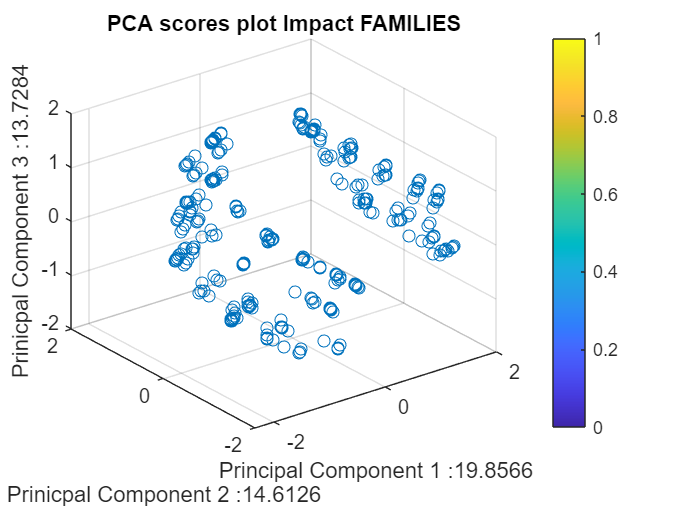

zlabel(strcat('Prinicpal Component 3 : ', num2str(impF.explained(3))))
% TODO: plot planes to distinguish groups 
% hold on
% x = [.4 .4];
% y = [0 1];
% z=[2 -2];
% line(x,y,z);
title('PCA scores plot Impact FAMILIES')
hold off

% from graph; if PC2 >0 -> 1group 
% PC2<0 and PC1 <0 ->froup 2
c1 = 1;c2 =1; c3 = 1;
first = zeros (length(impF.score),1);
second = zeros (length(impF.score),1);
third = zeros (length(impF.score),1);
for i=1:length(impF.score)
    if impF.score(i,2)> 0 
        first(c1) = i;
        c1 = c1+1;
    else
        if impF.score(i,1)< 0
            second(c2) = i;
            c2 = c2+1;
        else 
            third(c3) =i;
            c3 = c3+1;
        end
    end
end

GROUPS ARE NOT THE SAME!

    investigate which ones are not there 

% TODO: rename the arrays, the famalies one should have the extnesion
% _groups
fam=1;pca=1;
% save first the family then pca index of confusion, it will be consecutive
%pairs, if pca didnt identify -1 else 0?
anomalities1 = zeros(60,1);
counter=1;
for i=1:length(first)
    if first(i) == 0
        break
    end
    if first(i)== first_group(i)
   
    else
%       meaning pca didnt identify another of the group? -> -1
        if first(i)<first_group(i)
            anomalities1(counter)= first(fam)
            counter= counter+1;
             anomalities1(counter) = first_group(pca)
             counter= counter+1;
             anomalities1(counter) = -1
              counter= counter+1;
        else 
             anomalities1(counter)= first(fam)
            counter= counter+1;
             anomalities1(counter) = first_group(pca)
             counter= counter+1;
             anomalities1(counter) = 0
              counter= counter+1;
        end
    end
        fam= fam+1;
        pca= pca+1;

end

anomalities1 =     65
     0
     0
     0
     0
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
     0
     0
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
     0
     0
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
    66
     0
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
     0
     0
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
    67
     0
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
     0


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 =     65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 60×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 61×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 62×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 63×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 64×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 65×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 66×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 67×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 68×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 69×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 70×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 71×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 72×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 73×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 74×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 75×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 76×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 77×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 78×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 79×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 80×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 81×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 82×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 83×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 84×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 85×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 86×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 87×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 88×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 89×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 90×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 91×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 92×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 93×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 94×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 95×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 96×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 97×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 98×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 99×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 100×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 101×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 102×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 103×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 104×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 105×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 106×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 107×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 108×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 109×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 110×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 111×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 112×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 113×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 114×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 115×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 116×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 117×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 118×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 119×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 120×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 121×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 122×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 123×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 124×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 125×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 126×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 127×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 128×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 129×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 130×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 131×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 132×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 133×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 134×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 135×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 136×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 137×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 138×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 139×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 140×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 141×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 142×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 143×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 144×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 145×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 146×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 147×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 148×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 149×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 150×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 151×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 152×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 153×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 154×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 155×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 156×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 157×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 158×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 159×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 160×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 161×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 162×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 163×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 164×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 165×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 166×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 167×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 168×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 169×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 170×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 171×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 172×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 173×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 174×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 175×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 176×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 177×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 178×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 179×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 180×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 181×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 182×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 183×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 184×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 185×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 186×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 187×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 188×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 189×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 190×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 191×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 192×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 193×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 194×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 195×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 196×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 197×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 198×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 199×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 200×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 201×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 202×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 203×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 204×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 205×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 206×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 207×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 208×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 209×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 210×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 211×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 212×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 213×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 214×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 215×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 216×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 217×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 218×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 219×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 220×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 221×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 222×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 223×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 224×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 225×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 226×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 227×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 228×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 229×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 230×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 231×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 232×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 233×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 234×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 235×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 236×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 237×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 238×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 239×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 240×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 241×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 242×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 243×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 244×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 245×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 246×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 247×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 248×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 249×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 250×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 251×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 252×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 253×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 254×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 255×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 256×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 257×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 258×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 259×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 260×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 261×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 262×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 263×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 264×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 265×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 266×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 267×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 268×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 269×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 270×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 271×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 272×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 273×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 274×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 275×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 276×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 277×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 278×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 279×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 280×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 281×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 282×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 283×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 284×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 285×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 286×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 287×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 288×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 289×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 290×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 291×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 292×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 293×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 294×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 295×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 296×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 297×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 298×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 299×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 300×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 301×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 302×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 303×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 304×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 305×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 306×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 307×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 308×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 309×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 310×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 311×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 312×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 313×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 314×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 315×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 316×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 317×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 318×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 319×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 320×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


anomalities1 = 321×1
    65
    63
     0
    66
    64
     0
    67
    65
     0
    68


from anomalities, the first tuple is that LDPE with PA and PS1/2 is differnt than with PET; normal PCA identifies all LDPE as anotehr group

PCA identifies these as in the forst group and families dont 

HDPE1_PET1/ PS1/PET

PP1_PS1/PAI1/PET

PP2_PS1/PET

SECOND GROUP ARE THE SAME!!! :)))

% same constructionas with firs family
fam=1;pca=1;
anomalities2 = zeros(60,1);
counter2=1;
for i=1:length(second)
    if second(i)== second_group(i)
           
    else
%       meaning pca didnt identify another of the group? , family moves faster-> -1
        if second(i)<second_group(i)
            anomalities2(counter2) = second(fam)
            counter2 = 1+counter2
             anomalities2(counter2) = second_group(pca)
             counter2= counter2+1
             anomalities2(counter2) = -1
              counter2= counter2+1
        else 
%             PCA added instance into this group that families didnt
            anomalities2(counter2) = second(fam)
            counter2= counter2+1;
             anomalities2(counter2) = second_group(pca)
             counter2= counter2+1;
             anomalities2(counter2) = 0
              counter2= counter2+1;
        end
    end
        fam= fam+1;
        pca= pca+1;

end

anomalities2 = 60×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


counter2 = 2

anomalities2 = 60×1
     1
   220
     0
     0
     0
     0
     0
     0
     0
     0


counter2 = 3

anomalities2 = 60×1
     1
   220
    -1
     0
     0
     0
     0
     0
     0
     0


counter2 = 4

anomalities2 = 60×1
     1
   220
    -1
     2
     0
     0
     0
     0
     0
     0


counter2 = 5

anomalities2 = 60×1
     1
   220
    -1
     2
   221
     0
     0
     0
     0
     0


counter2 = 6

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     0
     0
     0
     0


counter2 = 7

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
     0
     0
     0


counter2 = 8

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
     0
     0


counter2 = 9

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     0


counter2 = 10

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 11

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 12

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 13

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 14

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 15

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 16

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 17

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 18

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 19

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 20

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 21

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 22

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 23

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 24

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 25

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 26

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 27

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 28

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 29

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 30

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 31

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 32

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 33

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 34

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 35

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 36

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 37

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 38

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 39

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 40

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 41

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 42

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 43

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 44

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 45

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 46

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 47

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 48

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 49

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 50

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 51

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 52

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 53

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 54

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 55

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 56

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 57

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 58

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 59

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 60

anomalities2 = 60×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 61

anomalities2 = 61×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 62

anomalities2 = 62×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 63

anomalities2 = 63×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 64

anomalities2 = 64×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 65

anomalities2 = 65×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 66

anomalities2 = 66×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 67

anomalities2 = 67×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 68

anomalities2 = 68×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 69

anomalities2 = 69×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 70

anomalities2 = 70×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 71

anomalities2 = 71×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 72

anomalities2 = 72×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 73

anomalities2 = 73×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 74

anomalities2 = 74×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 75

anomalities2 = 75×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 76

anomalities2 = 76×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 77

anomalities2 = 77×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 78

anomalities2 = 78×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 79

anomalities2 = 79×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 80

anomalities2 = 80×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 81

anomalities2 = 81×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 82

anomalities2 = 82×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 83

anomalities2 = 83×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 84

anomalities2 = 84×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 85

anomalities2 = 85×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 86

anomalities2 = 86×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 87

anomalities2 = 87×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 88

anomalities2 = 88×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 89

anomalities2 = 89×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 90

anomalities2 = 90×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 91

anomalities2 = 91×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 92

anomalities2 = 92×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 93

anomalities2 = 93×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 94

anomalities2 = 94×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 95

anomalities2 = 95×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 96

anomalities2 = 96×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 97

anomalities2 = 97×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 98

anomalities2 = 98×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 99

anomalities2 = 99×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 100

anomalities2 = 100×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 101

anomalities2 = 101×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 102

anomalities2 = 102×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 103

anomalities2 = 103×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 104

anomalities2 = 104×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 105

anomalities2 = 105×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 106

anomalities2 = 106×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 107

anomalities2 = 107×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 108

anomalities2 = 108×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 109

anomalities2 = 109×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 110

anomalities2 = 110×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 111

anomalities2 = 111×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 112

anomalities2 = 112×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 113

anomalities2 = 113×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 114

anomalities2 = 114×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 115

anomalities2 = 115×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 116

anomalities2 = 116×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 117

anomalities2 = 117×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 118

anomalities2 = 118×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 119

anomalities2 = 119×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 120

anomalities2 = 120×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 121

anomalities2 = 121×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 122

anomalities2 = 122×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 123

anomalities2 = 123×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 124

anomalities2 = 124×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 125

anomalities2 = 125×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 126

anomalities2 = 126×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 127

anomalities2 = 127×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 128

anomalities2 = 128×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 129

anomalities2 = 129×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 130

anomalities2 = 130×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 131

anomalities2 = 131×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 132

anomalities2 = 132×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 133

anomalities2 = 133×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 134

anomalities2 = 134×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 135

anomalities2 = 135×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 136

anomalities2 = 136×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 137

anomalities2 = 137×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 138

anomalities2 = 138×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 139

anomalities2 = 139×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 140

anomalities2 = 140×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 141

anomalities2 = 141×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 142

anomalities2 = 142×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 143

anomalities2 = 143×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 144

anomalities2 = 144×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 145

anomalities2 = 145×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 146

anomalities2 = 146×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 147

anomalities2 = 147×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 148

anomalities2 = 148×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 149

anomalities2 = 149×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 150

anomalities2 = 150×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 151

anomalities2 = 151×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 152

anomalities2 = 152×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 153

anomalities2 = 153×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 154

anomalities2 = 154×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 155

anomalities2 = 155×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 156

anomalities2 = 156×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 157

anomalities2 = 157×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 158

anomalities2 = 158×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 159

anomalities2 = 159×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 160

anomalities2 = 160×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 161

anomalities2 = 161×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 162

anomalities2 = 162×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 163

anomalities2 = 163×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 164

anomalities2 = 164×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 165

anomalities2 = 165×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 166

anomalities2 = 166×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 167

anomalities2 = 167×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 168

anomalities2 = 168×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 169

anomalities2 = 169×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 170

anomalities2 = 170×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 171

anomalities2 = 171×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 172

anomalities2 = 172×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 173

anomalities2 = 173×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 174

anomalities2 = 174×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 175

anomalities2 = 175×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 176

anomalities2 = 176×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 177

anomalities2 = 177×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 178

anomalities2 = 178×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 179

anomalities2 = 179×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 180

anomalities2 = 180×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 181

anomalities2 = 181×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 182

anomalities2 = 182×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 183

anomalities2 = 183×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 184

anomalities2 = 184×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 185

anomalities2 = 185×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 186

anomalities2 = 186×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 187

anomalities2 = 187×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 188

anomalities2 = 188×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 189

anomalities2 = 189×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 190

anomalities2 = 190×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 191

anomalities2 = 191×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 192

anomalities2 = 192×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 193

anomalities2 = 193×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 194

anomalities2 = 194×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 195

anomalities2 = 195×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 196

anomalities2 = 196×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 197

anomalities2 = 197×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 198

anomalities2 = 198×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 199

anomalities2 = 199×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 200

anomalities2 = 200×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 201

anomalities2 = 201×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 202

anomalities2 = 202×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 203

anomalities2 = 203×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 204

anomalities2 = 204×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 205

anomalities2 = 205×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 206

anomalities2 = 206×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 207

anomalities2 = 207×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 208

anomalities2 = 208×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 209

anomalities2 = 209×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 210

anomalities2 = 210×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 211

anomalities2 = 211×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 212

anomalities2 = 212×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 213

anomalities2 = 213×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 214

anomalities2 = 214×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 215

anomalities2 = 215×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 216

anomalities2 = 216×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 217

anomalities2 = 217×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 218

anomalities2 = 218×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 219

anomalities2 = 219×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 220

anomalities2 = 220×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 221

anomalities2 = 221×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 222

anomalities2 = 222×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 223

anomalities2 = 223×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 224

anomalities2 = 224×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 225

anomalities2 = 225×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 226

anomalities2 = 226×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 227

anomalities2 = 227×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 228

anomalities2 = 228×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 229

anomalities2 = 229×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 230

anomalities2 = 230×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 231

anomalities2 = 231×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 232

anomalities2 = 232×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 233

anomalities2 = 233×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 234

anomalities2 = 234×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 235

anomalities2 = 235×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 236

anomalities2 = 236×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 237

anomalities2 = 237×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 238

anomalities2 = 238×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 239

anomalities2 = 239×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 240

anomalities2 = 240×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 241

anomalities2 = 241×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 242

anomalities2 = 242×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 243

anomalities2 = 243×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 244

anomalities2 = 244×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 245

anomalities2 = 245×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 246

anomalities2 = 246×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 247

anomalities2 = 247×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 248

anomalities2 = 248×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 249

anomalities2 = 249×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 250

anomalities2 = 250×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 251

anomalities2 = 251×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 252

anomalities2 = 252×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 253

anomalities2 = 253×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 254

anomalities2 = 254×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 255

anomalities2 = 255×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 256

anomalities2 = 256×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 257

anomalities2 = 257×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 258

anomalities2 = 258×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 259

anomalities2 = 259×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 260

anomalities2 = 260×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 261

anomalities2 = 261×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 262

anomalities2 = 262×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 263

anomalities2 = 263×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 264

anomalities2 = 264×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 265

anomalities2 = 265×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 266

anomalities2 = 266×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 267

anomalities2 = 267×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 268

anomalities2 = 268×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 269

anomalities2 = 269×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 270

anomalities2 = 270×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 271

anomalities2 = 271×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 272

anomalities2 = 272×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 273

anomalities2 = 273×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 274

anomalities2 = 274×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 275

anomalities2 = 275×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 276

anomalities2 = 276×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 277

anomalities2 = 277×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 278

anomalities2 = 278×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 279

anomalities2 = 279×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 280

anomalities2 = 280×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 281

anomalities2 = 281×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 282

anomalities2 = 282×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 283

anomalities2 = 283×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 284

anomalities2 = 284×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 285

anomalities2 = 285×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 286

anomalities2 = 286×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 287

anomalities2 = 287×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 288

anomalities2 = 288×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 289

anomalities2 = 289×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 290

anomalities2 = 290×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 291

anomalities2 = 291×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 292

anomalities2 = 292×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 293

anomalities2 = 293×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 294

anomalities2 = 294×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 295

anomalities2 = 295×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 296

anomalities2 = 296×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 297

anomalities2 = 297×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 298

anomalities2 = 298×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 299

anomalities2 = 299×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 300

anomalities2 = 300×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 301

anomalities2 = 301×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 302

anomalities2 = 302×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 303

anomalities2 = 303×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 304

anomalities2 = 304×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 305

anomalities2 = 305×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 306

anomalities2 = 306×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 307

anomalities2 = 307×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 308

anomalities2 = 308×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 309

anomalities2 = 309×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 310

anomalities2 = 310×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 311

anomalities2 = 311×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 312

anomalities2 = 312×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 313

anomalities2 = 313×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 314

anomalities2 = 314×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 315

anomalities2 = 315×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 316

anomalities2 = 316×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 317

anomalities2 = 317×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 318

anomalities2 = 318×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 319

anomalities2 = 319×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 320

anomalities2 = 320×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 321

anomalities2 = 321×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 322

anomalities2 = 322×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 323

anomalities2 = 323×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 324

anomalities2 = 324×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 325

anomalities2 = 325×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 326

anomalities2 = 326×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 327

anomalities2 = 327×1
     1
   220
    -1
     2
   221
    -1
     3
   222
    -1
     4


counter2 = 328

THIRD GROUP

symmetry in what was found in first group, PCA considers  as part of second group LDPE with PET (NOK) and with PS1 (NOA), and families consideres it 1family

But also considers PS2 and PAI as third family


fam=1;pca=1;
anomalities3 = zeros(60,1);
counter3=1;
for i=1:length(third)
    if third(i)== third_group(i)
           
    else
%       meaning pca didnt identify another of the group? -> -1
        if third(i)<third_group(i)
            anomalities3(counter3) = third(fam)
            counter3 = 1+counter3
             anomalities3(counter3) = third_group(pca)
             counter3= counter3+1
             anomalities3(counter3) = -1
              counter3= counter3+1
        else 
            anomalities3(counter3) = third(fam)
            counter3= counter3+1;
             anomalities3(counter3) =third_group(pca)
             counter3= counter3+1;
             anomalities3(counter3) = 0
              counter3= counter3+1;
        end
    end
        fam= fam+1;
        pca= pca+1;

end

anomalities3 = 60×1
    63
     0
     0
     0
     0
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
     0
     0
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
     0
     0
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     0
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
     0
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     0
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
     0


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 60×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 61×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 62×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 63×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 64×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 65×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 66×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 67×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 68×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 69×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 70×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 71×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 72×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 73×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 74×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 75×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 76×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 77×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 78×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 79×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 80×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 81×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 82×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 83×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 84×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 85×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 86×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 87×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 88×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 89×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 90×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 91×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 92×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 93×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 94×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 95×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 96×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 97×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 98×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 99×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 100×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 101×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 102×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 103×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 104×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 105×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 106×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 107×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 108×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 109×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 110×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 111×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 112×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 113×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 114×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 115×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 116×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 117×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 118×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 119×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 120×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 121×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 122×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 123×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 124×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 125×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 126×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 127×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 128×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 129×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 130×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 131×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 132×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 133×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 134×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 135×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 136×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 137×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 138×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 139×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 140×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 141×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 142×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 143×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 144×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 145×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 146×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 147×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 148×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 149×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 150×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 151×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 152×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 153×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 154×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 155×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 156×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 157×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 158×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 159×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 160×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 161×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 162×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 163×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 164×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 165×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 166×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 167×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 168×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 169×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 170×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 171×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 172×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 173×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 174×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 175×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 176×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 177×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 178×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 179×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 180×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 181×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 182×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 183×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 184×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 185×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 186×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 187×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 188×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 189×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 190×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 191×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 192×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 193×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 194×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 195×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 196×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 197×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 198×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 199×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 200×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 201×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 202×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 203×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 204×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 205×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 206×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 207×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 208×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 209×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 210×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 211×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 212×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 213×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 214×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 215×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 216×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 217×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 218×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 219×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 220×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 221×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 222×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 223×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 224×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 225×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 226×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 227×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 228×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 229×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 230×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 231×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 232×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 233×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 234×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 235×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 236×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 237×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 238×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 239×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 240×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 241×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 242×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 243×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 244×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 245×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 246×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 247×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 248×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 249×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 250×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 251×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 252×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 253×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 254×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 255×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 256×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 257×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 258×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 259×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 260×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 261×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 262×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 263×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 264×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 265×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 266×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 267×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 268×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 269×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 270×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 271×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 272×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 273×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 274×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 275×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 276×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 277×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 278×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 279×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 280×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 281×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 282×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 283×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 284×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 285×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 286×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 287×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 288×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 289×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 290×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112


anomalities3 = 291×1
    63
     1
     0
    64
     2
     0
    70
     3
     0
   112



anom= zeros(60,1);c=1;
% for i=1:length(third )
% %     we want to see at what index PCA or families considers more than the
% %     other, in such case; jumping to another segment of family and PCA
% %     consoders other, families will have a higher index 
%     if third_group(i) > third(i:end)
%         anom(c)=third_group(i);c=c+1;
% 
% 
%     
% end


d = readtable('data_reduced.csv');

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H


standard = norm(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 26 27 28 29 30 31 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 ])
E = table(standard(:,:), norm(:,18),norm(:,22) , norm(:,32),norm(:, 36));
E = table2array(E);

% STRENGTH 
S = table2array(table(standard(:,:), norm(:,19),norm(:,23) , norm(:,33),norm(:, 37)));

% STRAIN BREAK 
SB = table2array(table(standard(:,:), norm(:,20),norm(:,24) , norm(:,34),norm(:, 38)));

% IMAPCT
I = table2array(table(standard(:,:), norm(:,21),norm(:,22) , norm(:,35),norm(:, 39)));


[red.coeff, red.score, red.latent, red.tsquared, red.explained, red.mu] = pca(d);

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

scatter3(red.score(:,1), red.score(:,2), red.score(:,3))
hold on
colorbar
xlabel(strcat('Principal Component 1 : ', num2str(red.explained(1))))
ylabel(strcat('Prinicpal Component 2 : ', num2str(red.explained(2))))'
zlabel(strcat('Prinicpal Component 3 : ', num2str(red.explained(3))))
title('PCA scores plot Impact')
hold off